Te = 0.3;

num = [1];
den = [1 1 0];

[numd, dend] = c2dm([num 0], den, Te, 'foh');
G = tf([numd 0], conv(dend, [1 -1]), Te);
G0 = feedback(G, 1)


G0 =
 
     0.1361 z^2 + 0.1231 z
  ----------------------------
  1.136 z^2 - 1.618 z + 0.7408
 
Sample time: 0.3 seconds
Discrete-time transfer function.


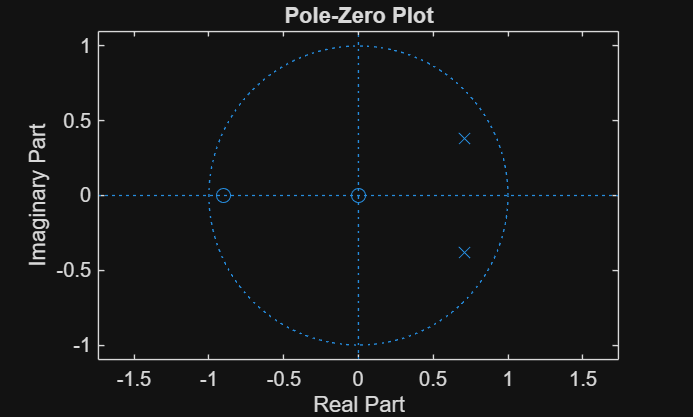


zplane(G0.Numerator{1},G0.Denominator{1})